## **Φόρτωση εικόνας**

clc; clear; close all;


% 1. Φόρτωση εικόνας (γκρι) από Images/Ασκηση 2
imgPath = fullfile('Images','Ασκηση 2','board.png');
I_orig = imread(imgPath);
if size(I_orig,3)==3
    I_gray = rgb2gray(I_orig);
else
    I_gray = I_orig;
end
I = double(I_gray);



## Ορισμός παραμέτρων


% 2. Παράμετροι
B = 32;                    % μέγεθος block
[M,N] = size(I);
rates = 5:5:50;            % ποσοστά r σε %
numRates = numel(rates);
MSE_zone = zeros(1,numRates);
MSE_thr  = zeros(1,numRates);

## Μέθοδοι ορισμός συντελετών


% 3. Διαίρεση σε blocks και συμπίεση για κάθε r
for ri = 1:numRates
    r = rates(ri)/100;
    K = round(r * B * B);            % αριθμός συντελεστών που θα κρατήσουμε
    rec_zone = zeros(M,N);
    rec_thr  = zeros(M,N);
    
    for ii = 1:B:M-B+1
        for jj = 1:B:N-B+1
            block = I(ii:ii+B-1, jj:jj+B-1);
            C = dct2(block);
            
            % 2.1 Μέθοδος Ζώνης (Zone):
            % Επιλέγουμε ορθογώνια ζώνη χαμηλών συχνοτήτων
            P = floor(sqrt(K));   % πλευρά του μεγάλου τετραγώνου
            mask_zone = false(B,B);                 % σαφώς BxB
            mask_zone(1:P,1:P) = true;
            rem = K - P^2;
            if rem>0 && P+1<=B
                % συμπλήρωση επιπλέον rem συντελεστών στην επόμενη γραμμή
                mask_zone(P+1,1:min(rem,B)) = true;
            end
            Cz = C .* mask_zone;                    % στοιχειομετρικός πολλαπλασιασμός
            rec_zone(ii:ii+B-1,jj:jj+B-1) = idct2(Cz);
            
            % 2.2 Μέθοδος Κατωφλίου (Threshold):
            absC = abs(C(:));
            sorted_vals = sort(absC,'descend');
            tau = sorted_vals(min(K,numel(sorted_vals)));
            mask_thr = abs(C)>=tau;                % BxB logical
            Ct = C .* mask_thr;
            rec_thr(ii:ii+B-1,jj:jj+B-1) = idct2(Ct);
        end
    end
    
    % 4. Υπολογισμός MSE με original
    MSE_zone(ri) = mean((I - rec_zone).^2,'all');
    MSE_thr(ri)  = mean((I - rec_thr ).^2,'all');
end

## Σχεδίαση  μέσου τετραγωνικού σφάλματος

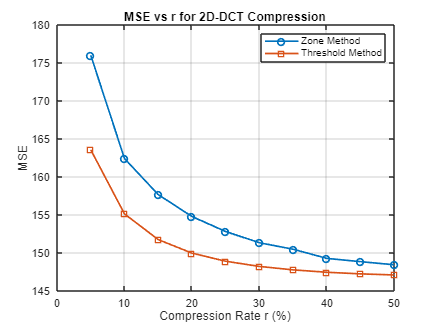


% 5. Σχεδίαση MSE vs r
figure('Name','MSE vs Compression Rate','NumberTitle','off');
plot(rates, MSE_zone, '-o', rates, MSE_thr, '-s','LineWidth',1.5);
xlabel('Compression Rate r (%)'); ylabel('MSE'); grid on;
legend('Zone Method','Threshold Method','Location','northeast');
title('MSE vs r for 2D-DCT Compression');


% 6. Δείγμα ανασύνθεσης για r=20%
r_sample = 20;
ri = find(rates==r_sample);
K = round(r_sample/100 * B * B);
recZ = zeros(M,N);
recT = zeros(M,N);
for ii = 1:B:M-B+1
    for jj = 1:B:N-B+1
        C = dct2(I(ii:ii+B-1,jj:jj+B-1));
        % zone mask
        P = floor(sqrt(K));
        maskZ = false(B,B);
        maskZ(1:P,1:P) = true;
        rem = K - P^2;
        if rem>0 && P+1<=B
            maskZ(P+1,1:min(rem,B)) = true;
        end
        recZ(ii:ii+B-1,jj:jj+B-1) = idct2(C .* maskZ);
        % threshold mask
        absC = abs(C(:));
        sorted_vals = sort(absC,'descend');
        tau = sorted_vals(min(K,numel(sorted_vals)));
        recT(ii:ii+B-1,jj:jj+B-1) = idct2(C .* (abs(C)>=tau));
    end
end

## Δείγματα αποσύνθεσης

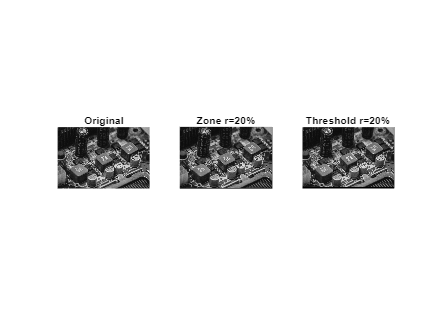


figure('Name',sprintf('Reconstruction at r=%d%%',r_sample),'NumberTitle','off');
subplot(1,3,1); imshow(uint8(I));   title('Original');
subplot(1,3,2); imshow(uint8(recZ)); title('Zone r=20%');
subplot(1,3,3); imshow(uint8(recT)); title('Threshold r=20%');